1. 计算白丁香和紫丁香的展叶期在同一个站点的平均值、中位数，极差，离差、离差平方和、方差和标准差、变异系数；再计算紫丁香在所有站点的偏度系数、峰度系数

clear;clc;
dx = readtable("丁香展叶期数据.xlsx","VariableNamingRule","preserve");

method 1

WandP = dx(:,["站点名ID","展叶期"]);
statarray = grpstats(WandP,"站点名ID",{'mean','median','range','var','std'})

statarray = 5×7 table
             站点名ID    GroupCount    mean_展叶期    median_展叶期    range_展叶期    var_展叶期    std_展叶期
             _______    __________    __________    ____________    ___________    _________    _________

    272         272         11          126.45          123             20          54.873       7.4076  
    22781     22781         11          71.909           72             52          187.69         13.7  
    23250     23250         11          72.273           72             29          71.018       8.4272  
    24508     24508          9          65.111           61             53          268.61       16.389  
    26353     26353         11          61.182           58             26          56.964       7.5474  


method 2

G = findgroups(categorical(table2array(dx(:,"站点名ID"))));
dx.("分组") = G;
% 平均数
meanTime = splitapply(@mean, dx.("展叶期"), G)

meanTime =   126.4545
   71.9091
   72.2727
   65.1111
   61.1818


dx.("平均数") = cell2mat(splitapply(@(x) {ones(size(x))*mean(x)}, dx.("展叶期"), G));

% 中位数 median
medianTime = splitapply(@median, dx.("展叶期"), G)

medianTime =    123
    72
    72
    61
    58


dx.("中位数") = cell2mat(splitapply(@(x) {ones(size(x))*median(x)}, dx.("展叶期"), G));

% 极差 range
rangeTime = splitapply(@range, dx.("展叶期"), G)

rangeTime =     20
    52
    29
    53
    26


dx.("极差") = cell2mat(splitapply(@(x) {ones(size(x))*range(x)}, dx.("展叶期"), G));

% 离差
deviationTime = splitapply(@(x){(x-min(x))/(max(x)-min(x))}, dx.("展叶期"), G)

deviationTime = 5×1 cell 数组
    {11×1 double}
    {11×1 double}
    {11×1 double}
    { 9×1 double}
    {11×1 double}


dx.("离差") = cell2mat(deviationTime);

% 离差平方和
sumdeviationTime = splitapply(@(x) sum(x-min(x))/(max(x)-min(x)), dx.("展叶期"), G)

sumdeviationTime =     5.7500
    6.5385
    5.0345
    3.2453
    3.8846


dx.("离差平方和") = cell2mat(splitapply(@(x) {ones(size(x))*sum(x-min(x))/(max(x)-min(x))}, dx.("展叶期"), G));

% 方差
varianceTime = splitapply(@var, dx.("展叶期"), G)

varianceTime =    54.8727
  187.6909
   71.0182
  268.6111
   56.9636


dx.("方差") = cell2mat(splitapply(@(x) {ones(size(x))*var(x)}, dx.("展叶期"), G));

% 标准差
standardDivTime = splitapply(@std, dx.("展叶期"), G)

standardDivTime =     7.4076
   13.7000
    8.4272
   16.3894
    7.5474


dx.("标准差") = cell2mat(splitapply(@(x) {ones(size(x))*std(x)}, dx.("展叶期"), G));

% 变异系数
coevTime = splitapply(@(x) std(x)./mean(x), dx.("展叶期"), G)

coevTime =     0.0586
    0.1905
    0.1166
    0.2517
    0.1234


dx.("变异系数") = cell2mat(splitapply(@(x) {ones(size(x))*(std(x)./mean(x))}, dx.("展叶期"), G));

writetable(dx,"第一题第一问.csv");

dxp = readtable("丁香展叶期数据.xlsx","VariableNamingRule","preserve");
rows = dxp.("物种") == "紫丁香";
dxp = dxp(rows,:);

% 偏度系数
skewTime = skewness(dxp.("展叶期"))

skewTime = 0.2583


% 峰度系数
kurtTime = kurtosis(dxp.("展叶期"))

kurtTime = 3.1356

2.计算农户家庭经营性纯收入的集中化指数及绘制洛伦兹曲线。

nh = readtable("1999年某地区农户家庭经营性纯收入水平及其构成.xlsx","VariableNamingRule","preserve");
nh = nh(1:9,:);
nh.("占总收入的比重/%") = nh.("收入/元") ./sum(nh.("收入/元")) * 100;
nh.("实际分布") = cumsum(sort(nh.("占总收入的比重/%"),"descend"));
temp = linspace(0,100,size(nh,1)+1);
temp = temp(2:size(nh,1)+1);
nh.("均匀分布") = permute(temp,[2 1]);
nh.("集中分布") = ones(size(nh,1),1).*100;

A = sum(nh.("实际分布"))

A = 763.6237

R = sum(nh.("均匀分布"))

R = 500

M = sum(nh.("集中分布"))

M = 900

I = (A - R)/(M - R)

I = 0.6591

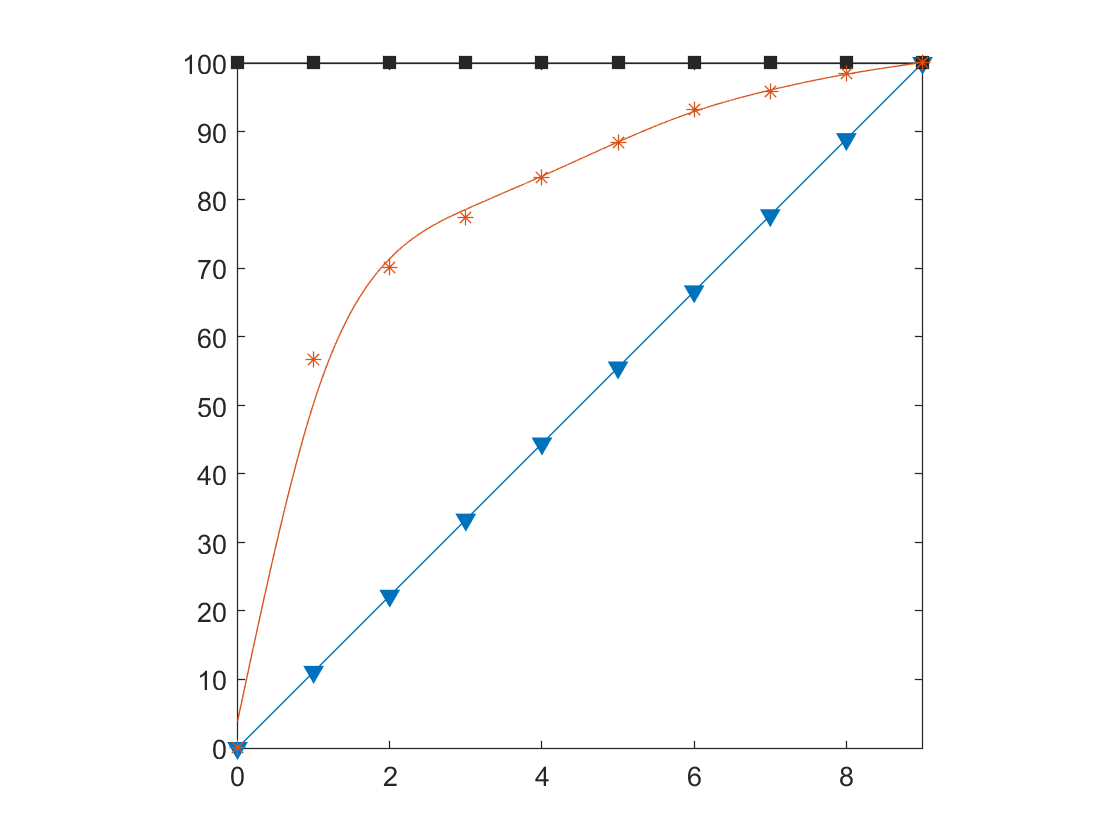


% 洛伦兹曲线

figure;
x = [0:size(nh,1)];
y2 = [0; nh.("均匀分布")];
plot(x',y2,'Marker','v','LineStyle','-','Color',[0 0.447058823529412 0.741176470588235],"MarkerFaceColor",[0 0.447058823529412 0.741176470588235]);
hold on

y3 = [100; nh.("集中分布")];
plot(x',y3,'Marker','square','LineStyle','-','Color',[0.149019607843137 0.149019607843137 0.149019607843137],"MarkerFaceColor",[0.149019607843137 0.149019607843137 0.149019607843137]);
hold on

x2 = 0:0.001:size(nh,1);
y1 = [0;nh.("实际分布")];
c = fit(x',y1,'smoothingspline');
d = c(x2);
plot(x',y1,'*',x2,d,'-',"Color",[0.850980392156863 0.325490196078431 0.0980392156862745],"MarkerFaceColor",[0.850980392156863 0.325490196078431 0.0980392156862745]);
hold on
xlim([0,9])
ylim([0,100])
axis square

max(a,[],"all")